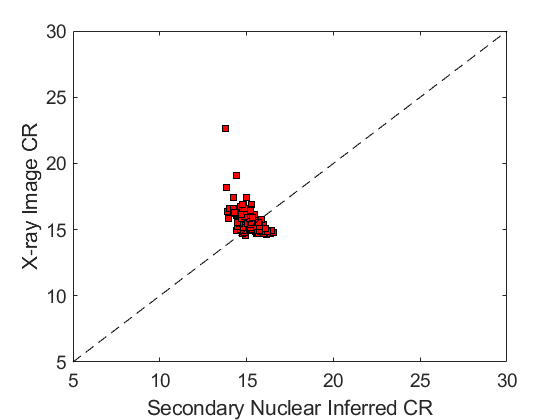

data = xlsread("Data.xlsx", "Sheet4");

nucCR = 1000 ./ data(:,2);
xrayCR = 1000 ./ data(:,3);
asym = data(:,14);

figure; hold on; box on;
xlim([5 30])
ylim([5 30])

xlabel('Secondary Nuclear Inferred CR')
ylabel('X-ray Image CR')
set(gca, 'FontSize', 14)

scatter(nucCR(:,1), xrayCR(:,1), 'filled', 'square', ...
    "MarkerEdgeColor", 'k',"MarkerFaceColor", 'r' )

plot([0 100], [0 100], '--k')

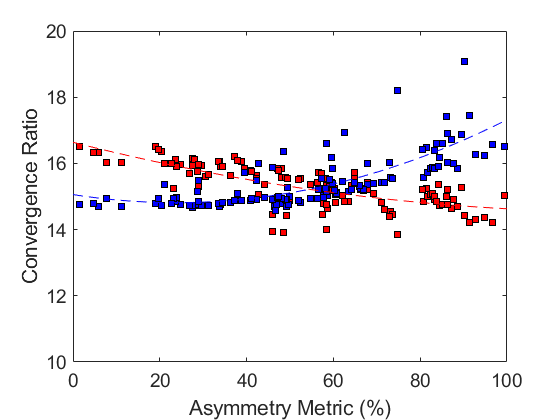



figure; hold on; box on;
xlim([0 100])
ylim([10 20])

xlabel('Asymmetry Metric (%)')
ylabel('Convergence Ratio')
set(gca, 'FontSize', 14)

scatter(100*asym, nucCR, 'filled', 'square', ...
    "MarkerEdgeColor", 'k',"MarkerFaceColor", 'r' )

scatter(100*asym, xrayCR, 'filled', 'square', ...
    "MarkerEdgeColor", 'k',"MarkerFaceColor", 'b' )

f = fit(100*asym, nucCR, 'poly2');
plot(0:100, f(0:100), '--r')

f = fit(100*asym, xrayCR, 'poly2');
plot(0:100, f(0:100), '--b')